# **This is question 1**

**1.a The question requires the creation of cosine wave with the given credentials:-**

Smapling frequency = 20kHz i.e number of time samples to be used are 20,000

sam_freq = 2e004;                   % represented in scientific notation
t = linspace(0,2,2*sam_freq);  

Frequency is last three digits of my Id. Hence. freq = 507 Hz (My Id is 0507)

f = 507;

Amplitude give is 2 units

sig_1a = 2*cos(2*pi*f*t);

**1.b  In this part, I will need to delay the time by100msec.**

error = 0.1;
correction = error*(ones(1,2*sam_freq));
new_t = t + correction;
sig_1b = 2*cos(2*pi*f*t);

Plotting the signal till 2 cycles only

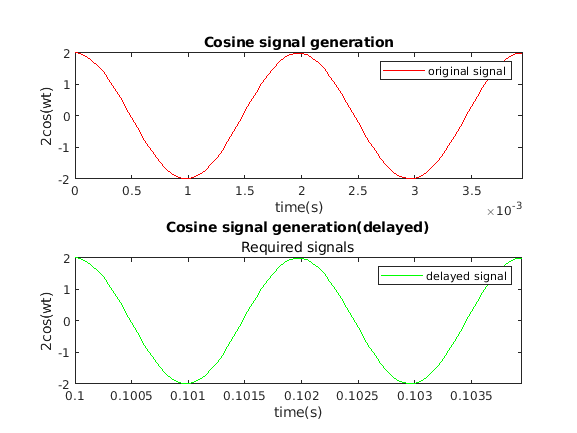

subplot(2,1,1),plot(t,sig_1a,'r'), legend('original signal');
title('Cosine signal generation');
xlabel('time(s)');
ylabel('2cos(wt)');
axis([0 2/f -2 2]);

subplot(2,1,2),plot(new_t,sig_1b,'g'), legend('delayed signal');
title('Cosine signal generation(delayed)');
xlabel('time(s)');
ylabel('2cos(wt)');axis([0.1 ((2/f)+0.1) -2 2]);

subtitle('Required signals');